# Intake: Flow to Cylinder

Given throttle command, compute the intake manifold pressure, which is required by the cylinder model.

## Volumetric Efficiency

The volume flow rate of air into the intake system is normally less efficient than the rate at which volume is displaced by the piston. This is the definition of volumetric efficiency, and its value range is normarlly between 0 and 1, but it can go over 1 in some efficient engines.

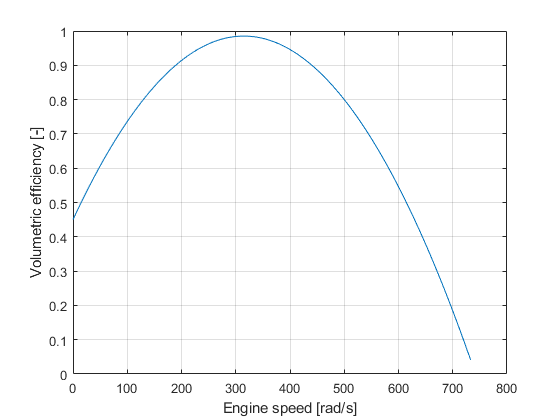

w_max = 7000/60*(2*pi) ;  % 'rad/s'
w = 0 : w_max ;

% These values are arbitrarily determined:
g_0 = 0.45;  % '1'
g_1 = 3.4e-3;  % '1/(rad/s)'
g_2 = -5.4e-6;  % '1/(rad/s)^2'

eff_v = g_0 + g_1*w + g_2*w.^2;

figure
plot(w, eff_v)
hold on
grid on
xlabel('Engine speed [rad/s]')
ylabel('Volumetric efficiency [-]')

## Mass flow to cylinder

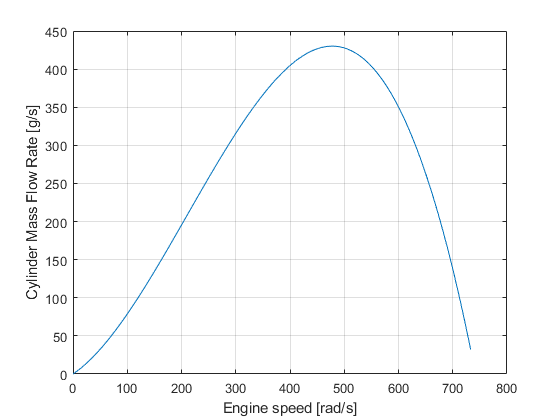

n_r = 2;  % 2 for four-stroke engine
R_air = 286;  % 'J/kg/K' .. specific gas constant of air
T_im = 273.15 + 25;  % 'K' .. intake air temperature
V_im = 2000;  % 'cm^3' .. intake manifold volume

p_im = 101325*0.9;  % 'Pa'

% w is defined as an array at the volumetric efficiency section above.
mdot_tocyl = (eff_v.*w) * (V_im*1e-6)*p_im/(n_r*(R_air/1000)*T_im);

figure
plot(w, mdot_tocyl)
hold on
grid on
xlabel('Engine speed [rad/s]')
ylabel('Cylinder Mass Flow Rate [g/s]')